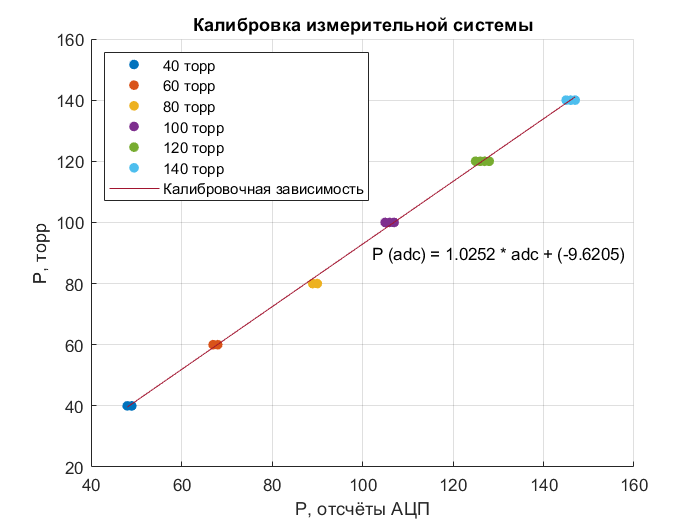

close all;
clear variables;

% Калибровка

data1 = importdata("C:\Users\Admin\Documents\get\get-for-10\blood\data\calibration_1.txt");
data2 = importdata("C:\Users\Admin\Documents\get\get-for-10\blood\data\calibration_2.txt");
data3 = importdata("C:\Users\Admin\Documents\get\get-for-10\blood\data\calibration_3.txt");
data4 = importdata("C:\Users\Admin\Documents\get\get-for-10\blood\data\calibration_4.txt");
data5 = importdata("C:\Users\Admin\Documents\get\get-for-10\blood\data\calibration_5.txt");
data6 = importdata("C:\Users\Admin\Documents\get\get-for-10\blood\data\calibration_6.txt");

cAdc = [data1; data2; data3; data4; data5; data6];
P_40 = ones(length(data1), 1) * 40;
P_60 = ones(length(data2), 1) * 60;
P_80 = ones(length(data3), 1) * 80;
P_100 = ones(length(data4), 1) * 100;
P_120 = ones(length(data5), 1) * 120;
P_140 = ones(length(data6), 1) * 140;

cP = [P_40; P_60; P_80; P_100; P_120; P_140];
l = polyfit(cAdc, cP, 1);

calibrF = figure('Name', 'Калибровка', 'NumberTitle', 'off');
hold all;

plot(data1, P_40, '.', 'MarkerSize', 20);
plot(data2, P_60, '.', 'MarkerSize', 20);
plot(data3, P_80, '.', 'MarkerSize', 20);
plot(data4, P_100, '.', 'MarkerSize', 20);
plot(data5, P_120, '.', 'MarkerSize', 20);
plot(data6, P_140, '.', 'MarkerSize', 20);

plot(cAdc, polyval(l, cAdc));

legend('40 торр', '60 торр', '80 торр', '100 торр', '120 торр', '140 торр', 'Калибровочная зависимость', 'Location', 'NorthWest');

grid on;
xlabel('P, отсчёты АЦП');
ylabel('P, торр');
title('Калибровка измерительной системы');
text(mean(cAdc)*1.05, mean(cP), ['P (adc) = ', num2str(l(1)), ' * adc + (', num2str(l(2)), ')']);

saveas(calibrF, "C:\Users\Admin\Documents\get\get-for-10\blood\calibration.png");

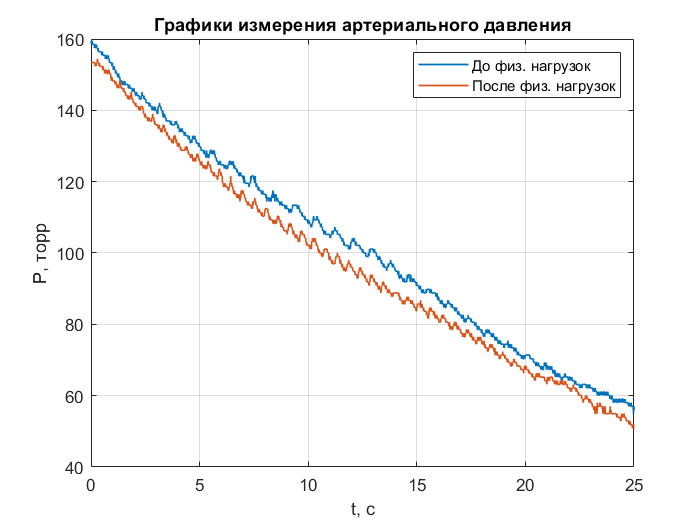


% Визуализация измерений

dt = 0.01;

adc_before = importdata('C:\Users\Admin\Documents\get\get-for-10\blood\data\data_before.txt');
t_before = linspace(0, length(adc_before)*dt, length(adc_before));
P_before = polyval(l, adc_before);

adc_after = importdata('C:\Users\Admin\Documents\get\get-for-10\blood\data\data_after.txt');
t_after = linspace(0, length(adc_after)*dt, length(adc_after));
P_after = polyval(l, adc_after);

PF = figure('Name', 'Давление до и после нагрузок', 'NumberTitle', 'off');
plot(t_before, P_before, t_after, P_after, "LineWidth", 1);
legend('До физ. нагрузок', 'После физ. нагрузок');

grid on;
xlim([0, 25]);
xlabel('t, с');
ylabel('P, торр');
title('Графики измерения артериального давления');

saveas(PF, "C:\Users\Admin\Documents\get\get-for-10\blood\P(t).png");

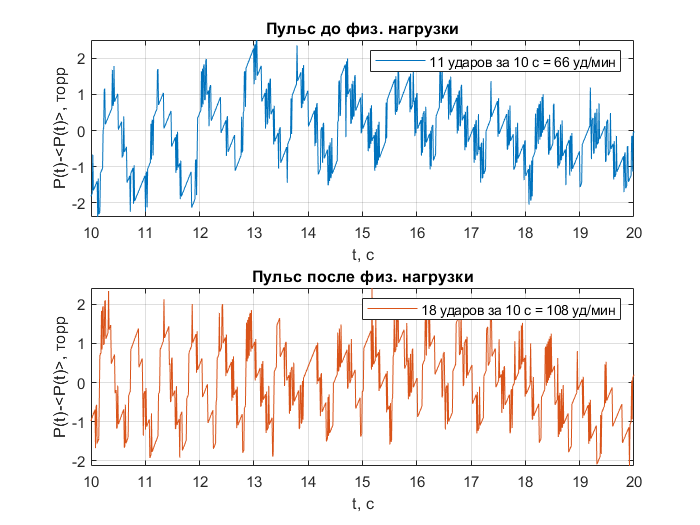


% Обработка данных (пульс)

c_before = polyfit(t_before, P_before, 7);
c_after = polyfit(t_after, P_after, 5);

pulse_before = P_before - polyval(c_before, t_before)';
pulse_after = P_after - polyval(c_after, t_after)';

pulseF = figure('Name', 'Графики пульса', 'NumberTitle', 'off');

subplot(2, 1, 1);
plot(t_before, pulse_before);
legend("11 ударов за 10 с = 66 уд/мин");
grid on;
xlim([10, 20]);
title("Пульс до физ. нагрузки");
xlabel('t, c');
ylabel('P(t)-<P(t)>, торр');

subplot(2, 1, 2);
plot(t_after, pulse_after, 'Color', [0.8500, 0.3250, 0.0980]);
legend("18 ударов за 10 с = 108 уд/мин");
grid on;
xlim([10, 20]);
title("Пульс после физ. нагрузки");
xlabel('t, c');
ylabel('P(t)-<P(t)>, торр');

saveas(pulseF, "C:\Users\Admin\Documents\get\get-for-10\blood\pulse.png");